% Import instron CSV data 
if 1 % Wrap in an "if" so the warnings all print at the end
    tab_instron_1 = readtable("StepStrainSweepPressure2_1.csv");
    tab_instron_2 = readtable("StepStrainSweepPressure2_2.csv");
    tab_instron_3 = readtable("StepStrainSweepPressure2_3.csv");
end

instron_data_tables = {tab_instron_1, tab_instron_2, tab_instron_3};

% Import pressure CSV data
tab_pressures_1 = readtable("07-08-2023-10-49-23.txt");
tab_pressures_2 = readtable("07-08-2023-10-55-50.txt");
tab_pressures_3 = readtable("07-08-2023-11-01-07.txt");
tab_pressures_1.Time = tab_pressures_1.Time - 0.3 * 1e4; % Manual time alignment correction
pressure_tables = {tab_pressures_1, tab_pressures_2, tab_pressures_3};

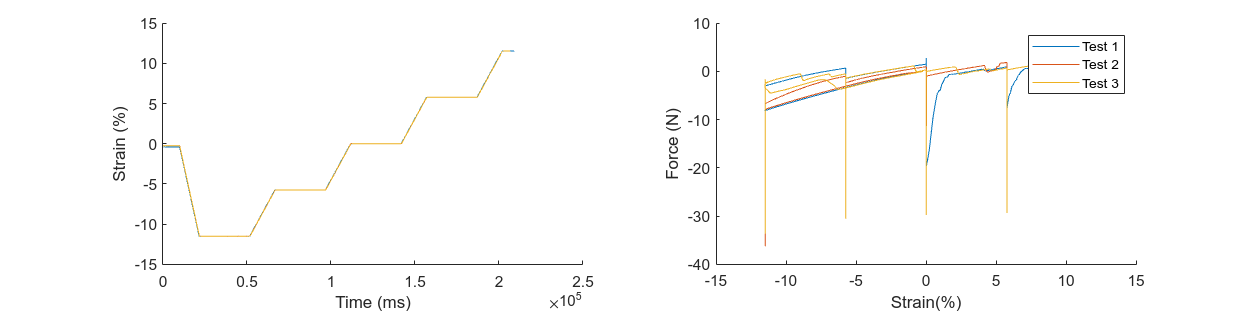

%% Visualize the instron data on its own.
fig = figure();
set(fig, "Position", [0, 0, 1600, 400])
subplot(1, 2, 1);
hold on;
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.Time, instron_data_tables{i}.TensileStrain_Displacement_);
end
xlabel("Time (ms)")
ylabel("Strain (%)")

subplot(1, 2, 2);
hold on
for i = 1 : length(instron_data_tables)
    plot(instron_data_tables{i}.TensileStrain_Displacement_, instron_data_tables{i}.Force);
end
xlabel("Strain(%)");
ylabel("Force (N)")
legend(["Test 1", "Test 2", "Test 3"]);

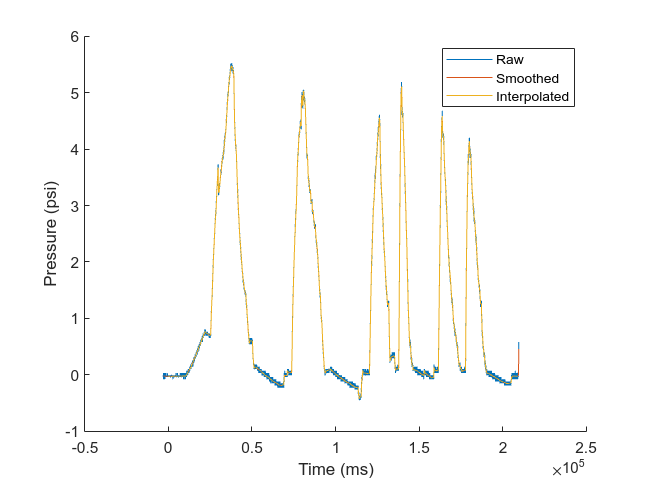

%% Visualize the pressure data and its smoothed versions
% NOTE: In the future, just call process_test()

% Smooth the pressures with a moving average
pressure_1_smoothed = smoothdata(tab_pressures_1.Pressure, "gaussian", 200);

% Interpolate pressures at the timestamps of the instron logs
[pressure_1_times_unique, i_times] = unique(tab_pressures_1.Time);
pressure_1_interp = interp1(pressure_1_times_unique, pressure_1_smoothed(i_times), tab_instron_1.Time);

fig = figure();
hold on;
plot(tab_pressures_1.Time, tab_pressures_1.Pressure);
plot(tab_pressures_1.Time, pressure_1_smoothed);
plot(tab_instron_1.Time, pressure_1_interp);

xlabel("Time (ms)")
ylabel("Pressure (psi)");
legend(["Raw", "Smoothed", "Interpolated"])

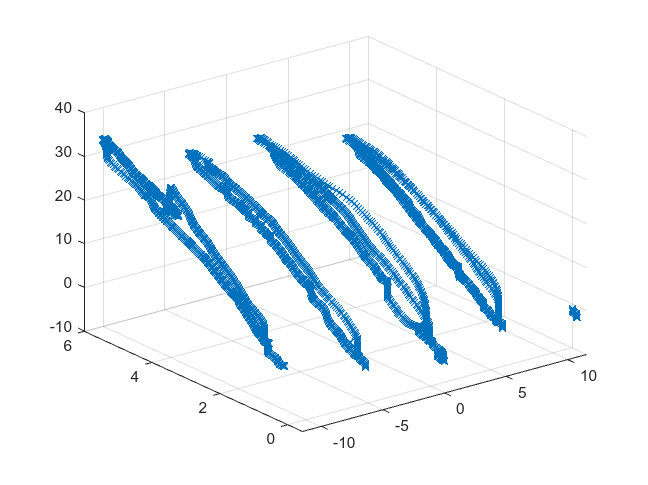

%% Create combiend-data table
% From here on out, we will use the table which combines pressure data with
% the rest of the instron data.
tab_combined_1 = process_test(tab_instron_1, tab_pressures_1);

figure()
i_holding = mod(tab_instron_1.Displacement, 5) < 0.1;
scatter3(tab_instron_1.TensileStrain_Displacement_(i_holding), pressure_1_interp(i_holding), -tab_instron_1.Force(i_holding), 'x');

% Batch process all datasets
n_datasets = length(pressure_tables);
combined_datasets = cell(1, n_datasets);
for i = 1 : n_datasets
    combined_datasets{i} = process_test(instron_data_tables{i}, pressure_tables{i});
end

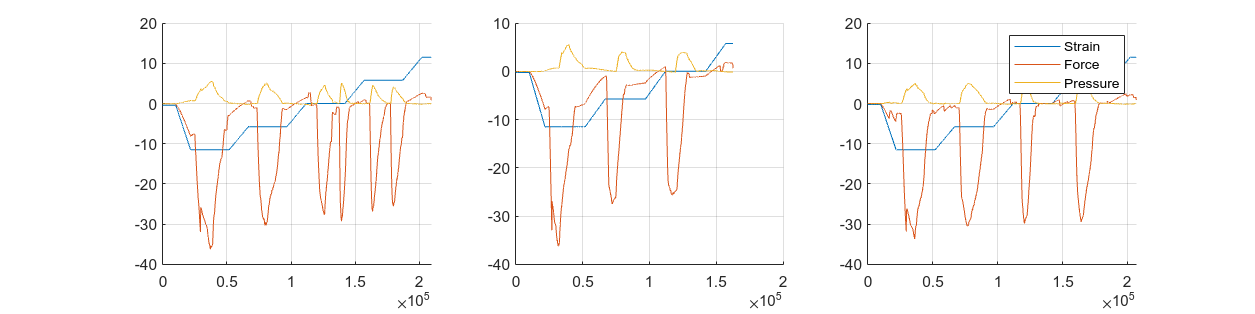

fig = figure();
set(fig, "Position", [0, 0, 1600, 400]);
for i = 1 : length(combined_datasets)
    subplot(1, length(combined_datasets), i);
    hold on
    
    dataset_i = combined_datasets{i};
    plot(dataset_i.Time, dataset_i.TensileStrain_Displacement_);
    plot(dataset_i.Time, dataset_i.Force);
    plot(dataset_i.Time, dataset_i.Pressure);
    grid on
end
legend("Strain", "Force", "Pressure")

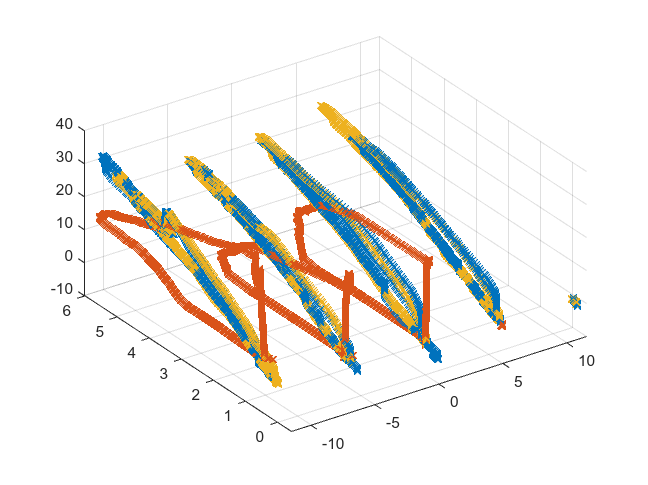

figure()
hold on;
for i = 1 : length(combined_datasets)
    dataset_i = combined_datasets{i};

    i_holding = mod(dataset_i.Displacement, 5) < 0.1;
    dataset_i_holding = dataset_i(i_holding, :);
    scatter3(...
        dataset_i_holding.TensileStrain_Displacement_,...
        dataset_i_holding.Pressure,...
        -dataset_i_holding.Force,...
        'x' ...
    )
end
view(-35, 45)
grid on

function tab_out = process_test(tab_instron, tab_pressure)
    % Smooth the pressures with a moving average
    pressure_smoothed = smoothdata(tab_pressure.Pressure, "gaussian", 200);
    
    % Interpolate pressures at the timestamps of the instron logs
    [pressure_times_unique, i_times] = unique(tab_pressure.Time);
    pressure_interp = interp1(pressure_times_unique, pressure_smoothed(i_times), tab_instron.Time);

    tab_out = tab_instron;
    tab_out.Pressure = pressure_interp;
end

function plot_time_alignment(tab_instron, tab_pressure)
    tab_combined = process_test(tab_instron, tab_pressure);

    figure()
    hold on
    plot(tab_combined.Time, tab_combined.Force);
    plot(tab_combined.Time, tab_combined.TensileStrain_Displacement_);
    plot(tab_combined.Time, tab_combined.Pressure);
    legend("Force", "Strain", "Pressre", "Location", "southeast");
end